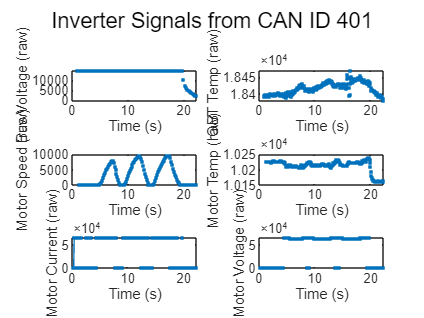

% Read CSV as text to preserve hex values
opts = detectImportOptions('T1.csv');
opts = setvartype(opts, 'char');   % all columns as text
rawData = readtable('T1.csv', opts);

% Skip header (first 7 rows)
rawData = rawData(8:end,:);

% Convert relevant columns
time   = str2double(rawData{:,1});      % timestamp
canID  = hex2dec(rawData{:,3});         % CAN ID in decimal
byte0  = hex2dec(rawData{:,6});         % first payload byte (signal ID)
byte1  = hex2dec(rawData{:,7});         % low byte of value
byte2  = hex2dec(rawData{:,8});         % high byte of value

% Build 16-bit value (assuming little endian: byte1 = LSB, byte2 = MSB)
value16 = byte1 + 256*byte2; %little endian
%value16 = 256*byte1 + byte2; %big endian

% Only look at inverter CAN frames (ID = 400 decimal = 0x190)
mask = (canID == 401);

% Preallocate result arrays (same length as data, NaN when not present)
busVoltage     = NaN(size(value16));
igbtTemp       = NaN(size(value16));
motorSpeed     = NaN(size(value16));
motorTemp      = NaN(size(value16));
motorCurrent   = NaN(size(value16));
motorVoltage   = NaN(size(value16));

% Decode depending on byte0
busVoltage(mask & byte0 == 235)   = value16(mask & byte0 == 235);
igbtTemp(mask & byte0 == 74)      = value16(mask & byte0 == 74);
motorSpeed(mask & byte0 == 168)   = value16(mask & byte0 == 168);
motorTemp(mask & byte0 == 73)     = value16(mask & byte0 == 73);
motorCurrent(mask & byte0 == 95)  = value16(mask & byte0 == 95);
motorVoltage(mask & byte0 == 138) = value16(mask & byte0 == 138);


motorSpeed(motorSpeed >= 32768) = motorSpeed(motorSpeed >= 32768) - 65536;


figure;

subplot(3,2,1);
plot(time, busVoltage, '.-')
xlabel('Time (s)'); ylabel('Bus Voltage (raw)');

subplot(3,2,2);
plot(time, igbtTemp, '.-')
xlabel('Time (s)'); ylabel('IGBT Temp (raw)');

subplot(3,2,3);
plot(time, (-1*motorSpeed), '.-')
xlabel('Time (s)'); ylabel('Motor Speed (raw)');

subplot(3,2,4);
plot(time, motorTemp, '.-')
xlabel('Time (s)'); ylabel('Motor Temp (raw)');

subplot(3,2,5);
plot(time, motorCurrent, '.-')
xlabel('Time (s)'); ylabel('Motor Current (raw)');

subplot(3,2,6);
plot(time, motorVoltage, '.-')
xlabel('Time (s)'); ylabel('Motor Voltage (raw)');

sgtitle('Inverter Signals from CAN ID 401');  % overall title

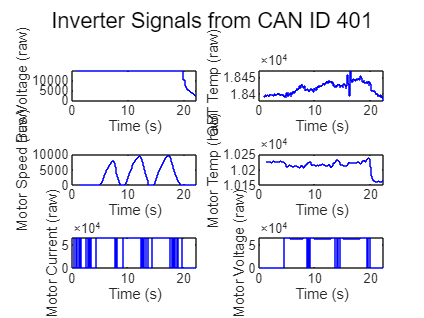

% Read CSV as text to preserve hex values
opts = detectImportOptions('T1.csv');
opts = setvartype(opts, 'char');   % all columns as text
rawData = readtable('T1.csv', opts);

% Skip header (first 7 rows)
rawData = rawData(8:end,:);

% Convert relevant columns
time   = str2double(rawData{:,1});      % timestamp
canID  = hex2dec(rawData{:,3});         % CAN ID in decimal

% Extract payload bytes as numeric
byte0  = hex2dec(rawData{:,6});
byte1  = hex2dec(rawData{:,7});
byte2  = hex2dec(rawData{:,8});
byte3  = hex2dec(rawData{:,9});
byte4  = hex2dec(rawData{:,10});
byte5  = hex2dec(rawData{:,11});
byte6  = hex2dec(rawData{:,12});
byte7  = hex2dec(rawData{:,13});

%% Filter messages for CAN ID = 9
mask9 = (canID == 9);

time_9  = time(mask9);
byte0_9 = byte0(mask9);
byte1_9 = byte1(mask9);
byte2_9 = byte2(mask9);
byte3_9 = byte3(mask9);
byte4_9 = byte4(mask9);
byte5_9 = byte5(mask9);
byte6_9 = byte6(mask9);
byte7_9 = byte7(mask9);

%% Decode signals (little-endian: low byte first)
busVoltagetx   = byte0_9 + 256*byte1_9;
%motorSpeedtx   = byte2_9 + 256*byte3_9;
motorCurrenttx = byte4_9 + 256*byte5_9;
motorVoltagetx = byte6_9 + 256*byte7_9;

%testing if needs to be signed
% Combine bytes as before
motorSpeedtx = byte2_9 + 256*byte3_9;
% Convert to signed 16-bit
motorSpeedtx(motorSpeedtx >= 32768) = motorSpeedtx(motorSpeedtx >= 32768) - 65536;

% %% Plot all four signals over time
% figure('Name','CAN ID 9 Signals','NumberTitle','off');
% 
% subplot(4,1,1)
% plot(time_9, busVoltagetx, 'b')
% title('Bus Voltage')
% ylabel('Voltage')
% grid on
% 
% subplot(4,1,2)
% plot(time_9, (-1*motorSpeedtx), 'r')
% title('Motor Speed')
% ylabel('Speed')
% grid on
% 
% subplot(4,1,3)
% plot(time_9, motorCurrenttx, 'g')
% title('Motor Current')
% ylabel('Current')
% grid on
% 
% subplot(4,1,4)
% plot(time_9, motorVoltagetx, 'm')
% title('Motor Voltage')
% ylabel('Voltage')
% xlabel('Time (s)')
% grid on
% 
% sgtitle('Decoded CAN ID 9 Signals')

figure;

subplot(3,2,1);
validIdx = ~isnan(busVoltage);
stairs(time(validIdx), busVoltage(validIdx), 'b')
xlabel('Time (s)'); ylabel('Bus Voltage (raw)');

subplot(3,2,2);
validIdx = ~isnan(igbtTemp);
stairs(time(validIdx), igbtTemp(validIdx), 'b')
xlabel('Time (s)'); ylabel('IGBT Temp (raw)');

subplot(3,2,3);
validIdx = ~isnan(motorSpeed);
stairs(time(validIdx), -1 * motorSpeed(validIdx), 'b')
xlabel('Time (s)'); ylabel('Motor Speed (raw)');

subplot(3,2,4);
validIdx = ~isnan(motorTemp);
stairs(time(validIdx), motorTemp(validIdx), 'b')
xlabel('Time (s)'); ylabel('Motor Temp (raw)');

subplot(3,2,5);
validIdx = ~isnan(motorCurrent);
stairs(time(validIdx), motorCurrent(validIdx), 'b')
xlabel('Time (s)'); ylabel('Motor Current (raw)');

subplot(3,2,6);
validIdx = ~isnan(motorVoltage);
stairs(time(validIdx), motorVoltage(validIdx), 'b')
xlabel('Time (s)'); ylabel('Motor Voltage (raw)');

sgtitle('Inverter Signals from CAN ID 401');  % overall title

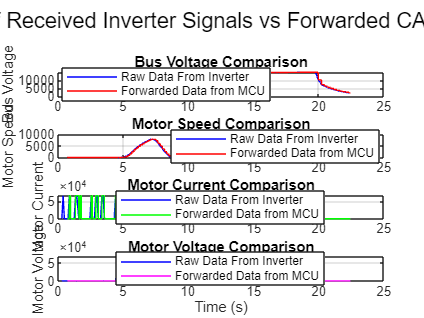

%% Only keep valid (non-NaN) samples for each inverter signal
validBusVoltage   = ~isnan(busVoltage);
validMotorSpeed   = ~isnan(motorSpeed);
validMotorCurrent = ~isnan(motorCurrent);
validMotorVoltage = ~isnan(motorVoltage);

%% Plot comparison for all four signals
figure('Name','Received vs Forwarded Signals','NumberTitle','off');

% Bus Voltage
subplot(4,1,1)
plot(time(validBusVoltage), busVoltage(validBusVoltage), 'b', 'DisplayName','Raw Data From Inverter');
hold on;
plot(time_9, busVoltagetx, 'r', 'DisplayName','Forwarded Data from MCU');
hold off;
ylabel('Bus Voltage')
title('Bus Voltage Comparison')
legend('Location','best')
grid on

% Motor Speed
subplot(4,1,2)
plot(time(validMotorSpeed), -1*motorSpeed(validMotorSpeed), 'b', 'DisplayName','Raw Data From Inverter');
hold on;
plot(time_9, -1*motorSpeedtx, 'r', 'DisplayName','Forwarded Data from MCU');
hold off;
ylabel('Motor Speed')
title('Motor Speed Comparison')
legend('Location','best')
grid on

% Motor Current
subplot(4,1,3)
plot(time(validMotorCurrent), motorCurrent(validMotorCurrent), 'b', 'DisplayName','Raw Data From Inverter');
hold on;
plot(time_9, motorCurrenttx, 'g', 'DisplayName','Forwarded Data from MCU');
hold off;
ylabel('Motor Current')
title('Motor Current Comparison')
legend('Location','best')
grid on

% Motor Voltage
subplot(4,1,4)
plot(time(validMotorVoltage), motorVoltage(validMotorVoltage), 'b', 'DisplayName','Raw Data From Inverter');
hold on;
plot(time_9, motorVoltagetx, 'm', 'DisplayName','Forwarded Data from MCU');
hold off;
ylabel('Motor Voltage')
xlabel('Time (s)')
title('Motor Voltage Comparison')
legend('Location','best')
grid on

sgtitle('Comparison of Received Inverter Signals vs Forwarded CAN ID 9 Signals');

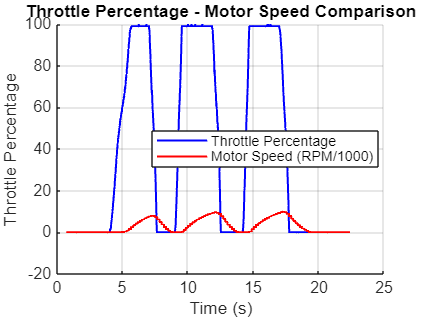

% --- Filter for CAN ID 8 ---
mask8 = (canID == 8);

time_8  = time(mask8);
byte1_8 = byte1(mask8);

% --- Remove NaN values just in case ---
validMask = ~isnan(time_8) & ~isnan(byte1_8);
time_8  = time_8(validMask);
byte1_8 = byte1_8(validMask);

% --- Plot byte 1 for ID 8 ---
figure;
hold on;

% Received data
plot(time_8, byte1_8, 'b', 'LineWidth', 1.2);


plot(time_8, (-1*motorSpeedtx)/1000, 'r', 'LineWidth', 1.2);

% Labels and title
xlabel('Time (s)');
ylabel('Throttle Percentage');
title('Throttle Percentage - Motor Speed Comparison');
grid on;

% Legend including scaling factor
legend('Throttle Percentage', 'Motor Speed (RPM/1000)', 'Location', 'best');

hold off;